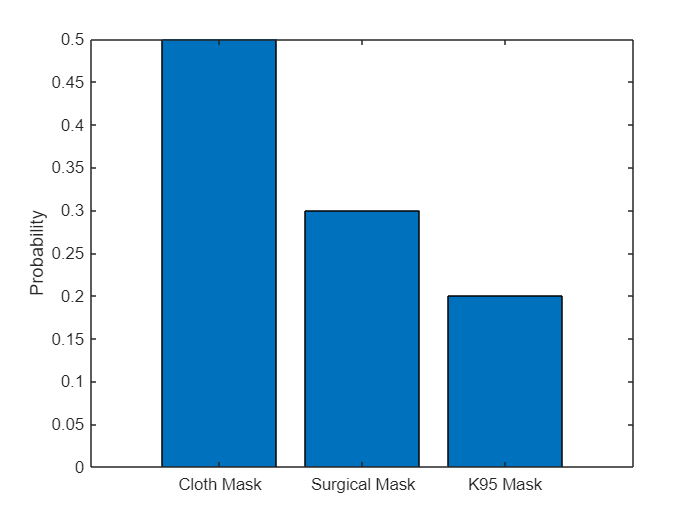

% mask efficacy
clothMaskEfficacy = .4;
surgicalMaskEfficacy = .7;
K95MaskEfficacy = .95;

% mask probability distribution (multinomial?)
clothMaskProb = 0.5;
surgicalMaskProb = 0.3;
K95MaskProb = 0.2;
pd_mask_probabilities = makedist('Multinomial','Probabilities',[clothMaskProb surgicalMaskProb K95MaskProb]);

% Visualize
maskOutcomes = categorical({'Cloth Mask','Surgical Mask','K95 Mask'});
maskOutcomes = reordercats(maskOutcomes,{'Cloth Mask','Surgical Mask','K95 Mask'});
x = 1:3;
pr = pd_mask_probabilities.pdf(x);
figure();
bar(maskOutcomes, pr)
ylabel('Probability')

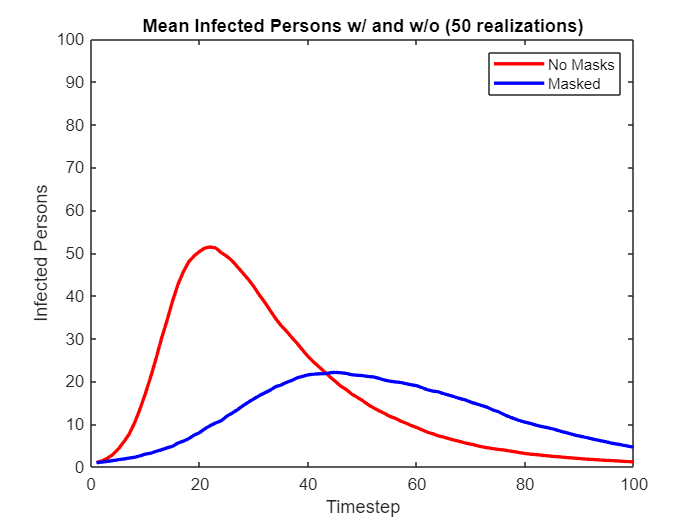

mask_matrix_random = random(pd_mask_probabilities, 100, 100);
mask_efficacy = [clothMaskEfficacy surgicalMaskEfficacy K95MaskEfficacy];
mask_matrix = mask_efficacy(mask_matrix_random); % converst from 1,2, and 3 to cloth, surgical, and K95 efficacy values (respectively)

% adjacency matrix 100 ppl
pop = 100;
no_mask_matrix = ones(pop,pop);

% Final Vulnerability Matrix
masked_vulnerability_matrix = no_mask_matrix - mask_matrix;
masked_vulnerability_matrix = masked_vulnerability_matrix.*-(eye(height(masked_vulnerability_matrix))-1);

% Simulate absir model w/ and w/o masks
    % Set the number of replications for the agent-based model
n_realizations = 100;
    % Run each simulation for 150 timesteps
T_simulation = 100;
    % Reserve space for simulation results
I_ensemble_no_mask = zeros(T_simulation, n_realizations);
I_ensemble_mask = zeros(T_simulation, n_realizations);
    % Set the random seed. This is something we'll talk about in the next module.
rng(101)
    % Set parameter values
infection_rate = 0.005;
recovery_rate = 0.05;

    % Generate the sample of results
for i = 1 : n_realizations
    % Run a single simulation
    Iv1 = zeros(pop, 1);
    Iv1(1) = 1;
    [Sh_mask, Ih_mask, Rh_mask] = simulate_absir(masked_vulnerability_matrix, Iv1, T_simulation, infection_rate, recovery_rate);
    [Sh_no_mask, Ih_no_mask, Rh_no_mask] = simulate_absir(no_mask_matrix, Iv1, T_simulation, infection_rate, recovery_rate);
    % Summarize and store the infection history
    I_ensemble_mask(:, i) = sum(Ih_mask, 1);
    I_ensemble_no_mask(:, i) = sum(Ih_no_mask, 1);
end

    % Compute the mean
I_mean_mask = mean(I_ensemble_mask, 2);
I_mean_no_mask = mean(I_ensemble_no_mask, 2);
meanPeak = max(I_mean_no_mask);
meanPeakPercent = meanPeak/pop * 100;
    % Visualize
figure()
plot(I_mean_no_mask, 'r-', 'LineWidth', 2.0, 'DisplayName', 'No Masks'); hold on
plot(I_mean_mask, 'b-', 'LineWidth', 2.0, 'DisplayName', 'Masked'); hold off
xlabel('Timestep')
ylabel('Infected Persons')
ylim([0 pop])
legend()
title('Mean Infected Persons w/ and w/o (50 realizations)')